## Extract Service Resources using Map Reduce

Requires the exported service samples of alibaba2022ms.mlx

[service_samples_export_file, ~, ~, ~, ~, ~] = config();
load('-mat', service_samples_export_file);
service_samples = export;
clear export;
disp(service_samples);

     service_id      cluster    trace_factor                                                                         involved_ms                                                                     
    _____________    _______    ____________    _____________________________________________________________________________________________________________________________________________________

    "S_79946648"        1         0.098634      {["MS_40139"    "MS_45753"    "USER"                                                                                                               ]}
    "S_62583430"        1         0.098634      {["MS_58809"    "MS_9076"    "USER"                                                                                                                ]}
    "S_6505908"         1         0.098634      {["MS_13825"    "MS_578

clear service_samples_export_file;

### Parallelism

Parts of this script profit from parallel execution (requires Parallel Computing Toolbox)

**Run only one of two sections below...**

### Enabling parallel computing

Run this scetion to (re-)enable parallel mapreducing

Note: The debugger will not work within map-reduce parts while this is ON

mapreducer(gcp);

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 6 workers.


### Disabling parallel computing

Run this scetion to disable parallel mapreducing

Note: This will allow the debugging of map-reduce parts.

mapreducer(0);

## Actual Script below

### Service filter

List of services we are interested in

% All MS in once list (with duplicates)
involved_ms_with_duplicates = horzcat(service_samples.involved_ms{:})';
% Unique List (but still has 'USER' ms)
involved_ms_unique_incl_user = unique(involved_ms_with_duplicates);
% Unique clean list without 'USER'
involved_ms = involved_ms_unique_incl_user(~strcmp(involved_ms_unique_incl_user, "USER"))
clear involved_ms_with_duplicates;
clear involved_ms_unique_incl_user;

### Prepare selected columns for Trace CSV reading

[trace_header, trace_formats, trace_vartypes] = trace_constants();
ignore_columns = ["response_time", "trace_id", "service", "rpc_id", "rpc_type", "upstream_ms", "upstream_instance", "interface"];
used_col_idx = ~ismember(trace_header, ignore_columns);
trace_selected_cols = trace_header(used_col_idx);
trace_selected_vartypes = trace_vartypes(used_col_idx);
trace_selected_formats = trace_formats(used_col_idx);

clear trace_formats;
clear trace_vartypes;
clear ignore_columns;

### Create Trace Datastore

Read in .csv and create a datastore that can be used with mapreduce.

[trace_location, trace_header_lines] = trace_config();
trace_ds = tabularTextDatastore(trace_location, "NumHeaderLines", trace_header_lines, ...
    "RowDelimiter", "\n", ...
    "Delimiter", ",", ...
    "TreatAsMissing", "None", ...

ans = 8×3 table
    timestamp    downstream_ms     downstream_instance 
    _________    _____________    _____________________

     115352      {'MS_71712'}     {'MS_71712_POD_244' }
      86450      {'MS_24094'}     {'MS_24094_POD_5168'}
      86450      {'MS_24094'}     {'MS_24094_POD_5168'}
     155753      {'MS_67455'}     {'MS_67455_POD_222' }
      90649      {'UNKNOWN' }     {'UNKNOWN'          }
      90664      {'MS_10343'}     {'MS_10343_POD_5'   }
     167154      {'MS_60125'}     {'MS_60125_POD_5'   }
     152182      {'MS_66701'}     {'MS_66701_POD_10'  }


    "MissingValue", 0, ...
    "VariableNames", trace_header, ...
    "SelectedFormats", trace_selected_formats, ...
    "SelectedVariableNames", trace_selected_cols);

clear trace_location;
clear trace_header_lines;
clear trace_selected_formats;

preview(trace_ds)

### Map Reduce to find downstream_ms close to metric sampling intervals

We want to find out how many calls happen just before a MS metric sampling point, so we can extract how many resources are being used by a specific service per call and as baseline.

- Only takes traces where downstream_ms is a member of 'involved_ms'

- Only takes traces where timestamp is within 'tolerance_ms' of the sampling interval

% every 60s
resource_sampling_interval_ms = 60 * 1000;
% start high, with 10ms before sampling TS
tolerance_ms = 10;
% wrap mapper function to pass variable context

Parallel mapreduce execution on the parallel pool:
********************************
*      MAPREDUCE PROGRESS      *
********************************
Map   0% Reduce   0%
Map   1% Reduce   0%
Map   2% Reduce   0%
Map   3% Reduce   0%
Map   4% Reduce   0%
Map   5% Reduce   0%
Map   6% Reduce   0%
Map   7% Reduce   0%
Map   8% Reduce   0%
Map   9% Reduce   0%
Map  10% Reduce   0%
Map  11% Reduce   0%
Map  12% Reduce   0%
Map  13% Reduce   0%
Map  14% Reduce   0%
Map  15% Reduce   0%
Map  16% Reduce   0%
Map  17% Reduce   0%
Map  18% Reduce   0%
Map  19% Reduce   0%
Map  20% Reduce   0%
Map  21% Reduce   0%
Map  22% Reduce   0%
Map  23% Reduce   0%
Map  24% Reduce   0%
Map  25% Reduce   0%
Map  26% Reduce   0%
Map  27% Reduce   0%
Map  28% Reduce   0%
Map  29% Reduce   0%
Map  30% Reduce   0%
Map  31% Reduce   0%
Map  32% Reduce   0%
Map  33% Reduce   0%
Map  34% Reduce   0%
Map  35% Reduce   0%
Map  36% Reduce   0%
Map  37% Reduce   0%
Map  38% Reduce   0%
Map  39% Reduce   0%
Map  40% R

mapFunc = @(a, b, c)trace_mapper(a, b, c, involved_ms, resource_sampling_interval_ms, tolerance_ms);

Elapsed time is 197.830889 seconds.


% wrap reducer function to pass empty table obj
empty_table = table('Size', [0 length(trace_selected_vartypes)], 'VariableTypes',trace_selected_vartypes, 'VariableNames',trace_selected_cols);
reduceFunc = @(a, b, c)trace_reducer(a, b, c, empty_table);
tic
trace_metrics_ds = mapreduce(trace_ds, mapFunc, reduceFunc, 'OutputFolder', './results');
toc
clear empty_table;
clear col_idx_trace_id;
clear mapFunc;
clear reduceFunc;

### Read result and prepare table to match with metrics

e.g. for each entry we want to have the corresponding sampling timestamp

trace_metrics = prepare_trace_metrics(readall(trace_metrics_ds));

### Create Datastore for Metrics

Read in .csv and create a datastore that can be used with mapreduce.

[ms_metrics_header, ms_metrics_formats, ~] = constants();
[~, ms_metrics_location, ms_metrics_header_lines, ~, ~, ~] = config();
metrics_ds = tabularTextDatastore(ms_metrics_location, "NumHeaderLines", ms_metrics_header_lines, ...
    "RowDelimiter", "\n", ...
    "Delimiter", ",", ...
    "TreatAsMissing", "None", ...
    "MissingValue", 0, ...
    "VariableNames", ms_metrics_header, ...
    "SelectedFormats", ms_metrics_formats, ...
    "SelectedVariableNames", ms_metrics_header);

clear ms_metrics_header;
clear ms_metrics_formats;
clear ms_metrics_location;
clear ms_metrics_header_lines;
clear ms_metrics_selected_formats;

prev_metrics_ds = copy(metrics_ds);
reset(prev_metrics_ds);
prev_metrics_ds.ReadSize = 10;
read(prev_metrics_ds)

ans = 10×6 table
    timestamp      ms_name          ms_instance_id          node_id        cpu_utilization    memory_utilization
    _________    ____________    ____________________    ______________    _______________    __________________

      300000     {'MS_68185'}    {'MS_68185_POD_91' }    {'NODE_20236'}        0.17238             0.66236      
      420000     {'MS_25215'}    {'MS_25215_POD_372'}    {'NODE_36528'}       0.085708             0.43286      
      720000     {'MS_31285'}    {'MS_31285_POD_916'}    {'NODE_23966'}        0.44523             0.57209      
      780000     {'MS_42019'}    {'MS_42019_POD_38' }    {'NODE_34880'}       0.091057             0.52934      
      900000     {'MS_9482' }    {'MS_9482_POD_332' }    {'NODE_45529'}        0.17766             0

clear prev_metrics_ds;

### Filter MsMetrics using Map Reduce

For the services we care about and within the timelimit we want.

[~, ~, ~, ms_metrics_max_timestamp, ~, metrics_output_file] = config();

% Wrap mapFun to pass involved_ms
mapFunc = @(a, b, c)metrics_mapper(a, b, c, ms_metrics_max_timestamp, involved_ms);
reduceFunc = @(a, b, c)metrics_reducer(a, b, c);
filtered_metrics_ds = mapreduce(metrics_ds, mapFunc, reduceFunc, 'OutputFolder', './results', 'Display', 'off');

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 6 workers.


entries = readall(filtered_metrics_ds);
flatter = vertcat(entries{:,2});
filtered_metrics = sortrows(vertcat(flatter{:,1}), "ms_name", "ascend");

fprintf("Writing filtered metrics from 0-%i millis to file '%s'", ms_metrics_max_timestamp, metrics_output_file);

Writing filtered metrics from 0-3600000 millis to file '../metrics.csv'

writetable(filtered_metrics, metrics_output_file, "Delimiter", "\t");

clear filtered_metrics_ds;
clear entries;
clear flatter;
clear mapFunc;
clear reduceFunc;
clear metrics_output_file;
clear ms_metrics_max_timestamp;

### Join Metrics with trace counts

metrics_with_trace_count = join_metrics_and_traces(filtered_metrics, trace_metrics);

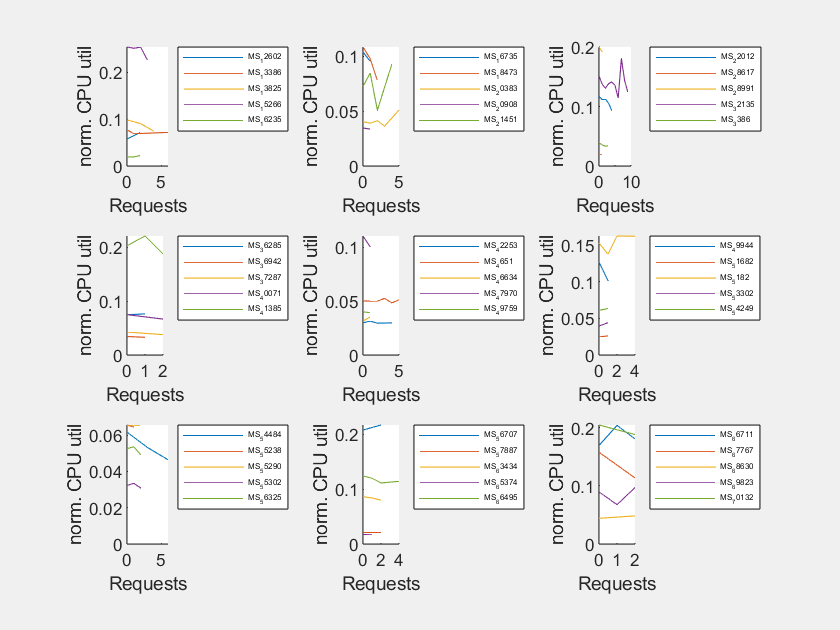

metrics_mean_by_trace_count = groupsummary(metrics_with_trace_count, ["ms_name", "requests"], "mean", ["cpu_utilization", "memory_utilization"]);
metrics_requests_analysis_plots(metrics_mean_by_trace_count, "cpu", {[0 Inf] "linear"});